# Detecting edges

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity. 

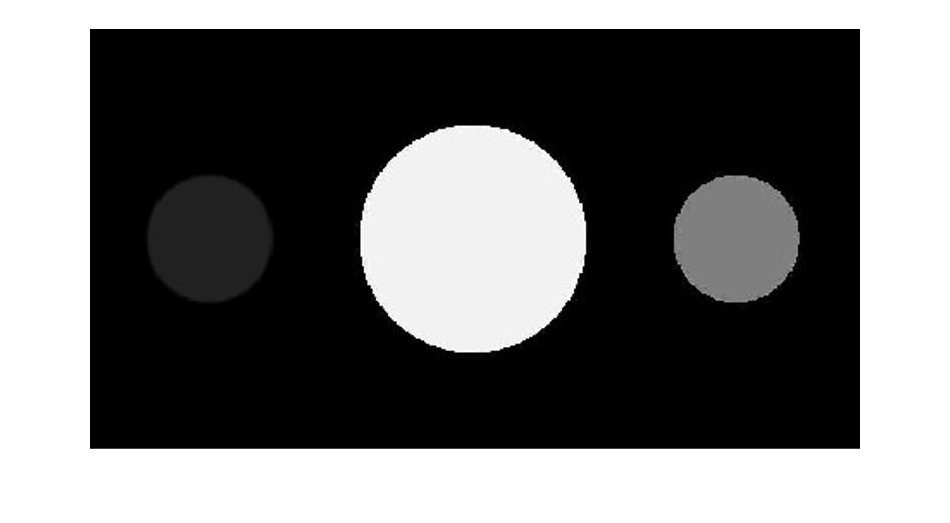

circles = imread("./images/circles.jpg");
imshow(circles)

## Task 1

You can locate the edges of well-defined objects in a grayscale image by calling the `edge` function without specifying a threshold.

`defaultEdges` `=` `edge``(``gs``)`

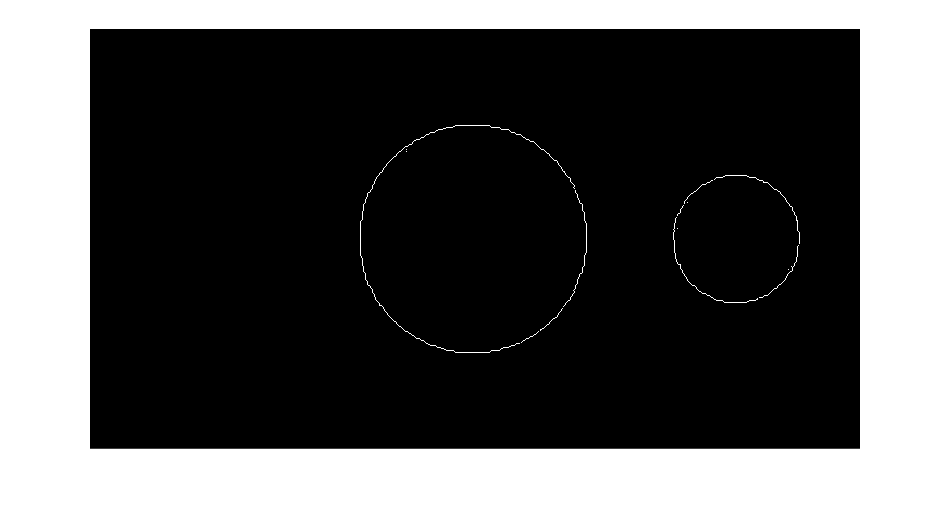

circEdge = edge(circles);
imshow(circEdge)

## Task 2

The edges of two circles were identified, but the boundary of the third faint circle was missed due to low contrast. You can lower the detection threshold to capture the boundary of the third circle.

It's useful to know the default threshold chosen by `edge` to inform the selection of a new threshold. You can extract the default threshold by adding a second output to `edge`.

`[``defaultEdges``,``thresh``]` `=` `edge``(``gs``)`

[circEdge, thresh] = edge(circles)

circEdge = 419×770 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

thresh = 0.0589

## Task 3

Now that you have the default threshold, you can lower it to detect the edges of the third circle.

`adjustedEdges` `=` `edge``(``gs``,``threshold``)`

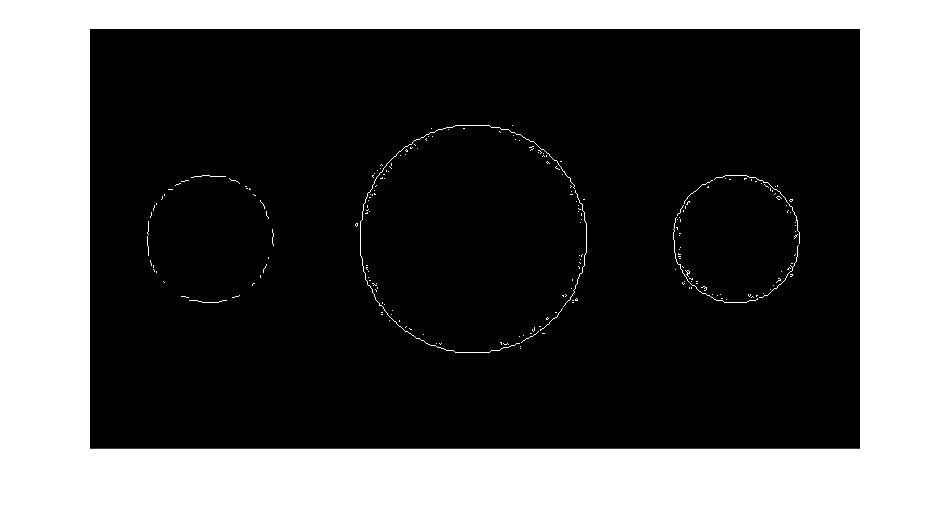

adjEdge = edge(circles, thresh/2);
imshow(adjEdge)

## Task 4

Did you notice that the edges of the third circle were found but are a bit broken up? Another way to tune the detection is to select a different edge detection algorithm.

`[``adjustedEdges``,``thresh``]` `=` `edge``(``gs``,``method``)`

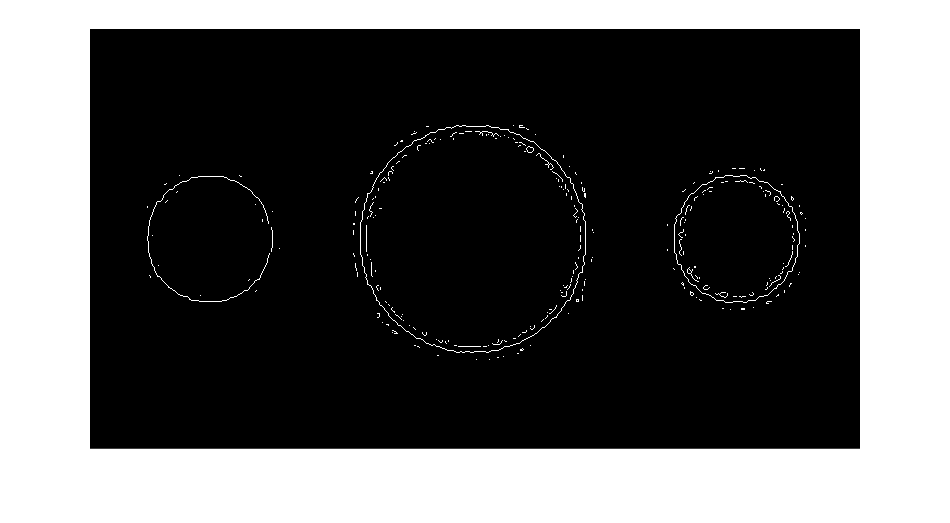

[adjEdge, thresh] = edge(circles, "log");
imshow(adjEdge)